**Lee and Shetzen cross correlation technique**

In this programm I will apply the cross correletion technique of Lee and Shetzen to examine the Wiener kernals of the system. After these are found the corresponding Volterra functionals will be determined.

**Loading the data**

load Jochem.mat %loading data file 

**Auto correlation property of the GWN data**

Firstly we need to check that the GWN data fullfills the auto-correlation property, the autocorrelation should be equal to the mean of the data squared, which will be 0 in the case of GWN data. The expectation value of the data should also equal 0 for odd, and 1 for even powers of the gwn signal.

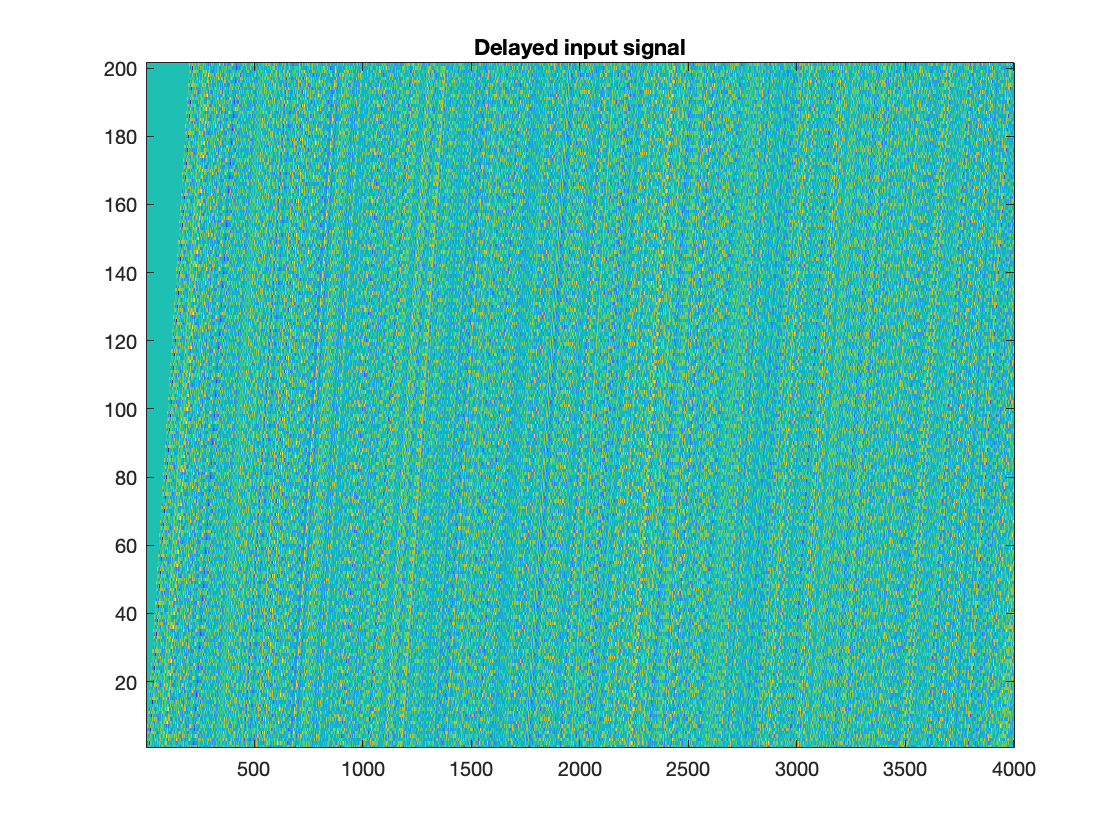

%gwnt = 0.5 * randn(1,4000);
%gwnt2 = 0.5 * randn(1,4000);

a_corr_gwn_xx=phi_yx2(gwnt,gwnt,200);

EGWN1=mean(gwnt) %indeed see that the mean of the gwn signal is about 0

EGWN1 = 0.0108

EGWN2=mean(gwnt.*gwnt) %and that the product has a mean of about 1

EGWN2 = 0.9971

EGWN3=mean(gwnt.*gwnt.*gwnt)

EGWN3 = 0.0289

EGWN4=mean(gwnt.*gwnt.*gwnt.*gwnt)

EGWN4 = 2.9136

EGWN5=mean(gwnt.*gwnt.*gwnt.*gwnt.*gwnt)

EGWN5 = 0.1183

EGWN6=mean(gwnt.*gwnt.*gwnt.*gwnt.*gwnt.*gwnt)

EGWN6 = 14.2454

disp(max(abs(a_corr_gwn_xx))); %the maximum result from the integral is small, so the

    0.2898



%gwn signal indeed has about a zero autocorrelation. 
disp(length(a_corr_gwn_xx))

   201



disp(var(gwnt))

    0.9972



disp(std(gwnt).^2) %so the gwnt signal stored in the jochem.mat file has a power of ~1

    0.9972



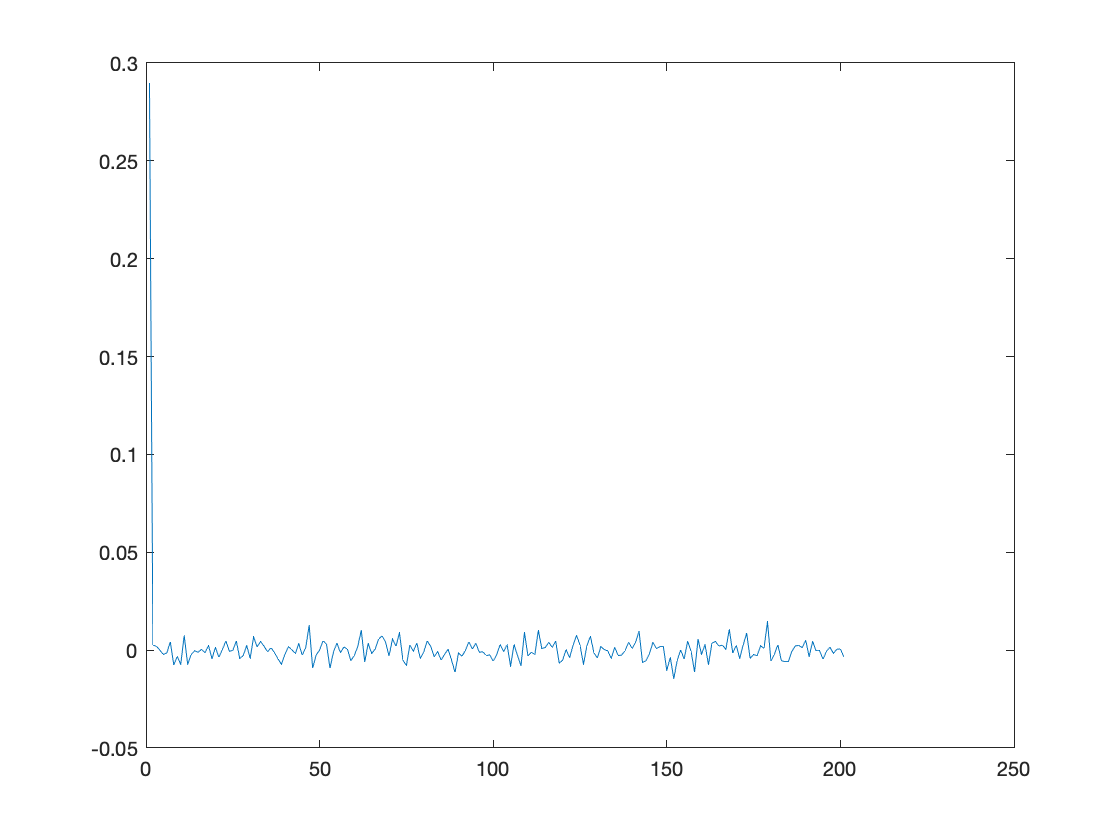

plot(a_corr_gwn_xx)

In the code above we see that indeed the mean of the GWN signal is about 0. And we see that for a product of an even number of GWN signals the expectation is indeed about 1, where it is about 0 for an odd number of GWN signals in the product.

The maximum result from the integral is small, so the gwn signal indeed has about a zero autocorrelation. Note that the result varries for different time differences, M, that are used. For M=0 I obtain 1, which is expected as these are identical (and the result should be a dirac delta which is 1 if the timing is the exact same). For large M (eg. M=2000), this results in an correlation of ~0.04 (so very small). If the data is shifted less, so M is smaller, the maximum of the correlation becomes larger.

Need a peak in the autocorrelation at 0, and then it should be flat. Also power distribution should be flat.

**Exploring the wiener function**

P = 0.4961

    1.0000



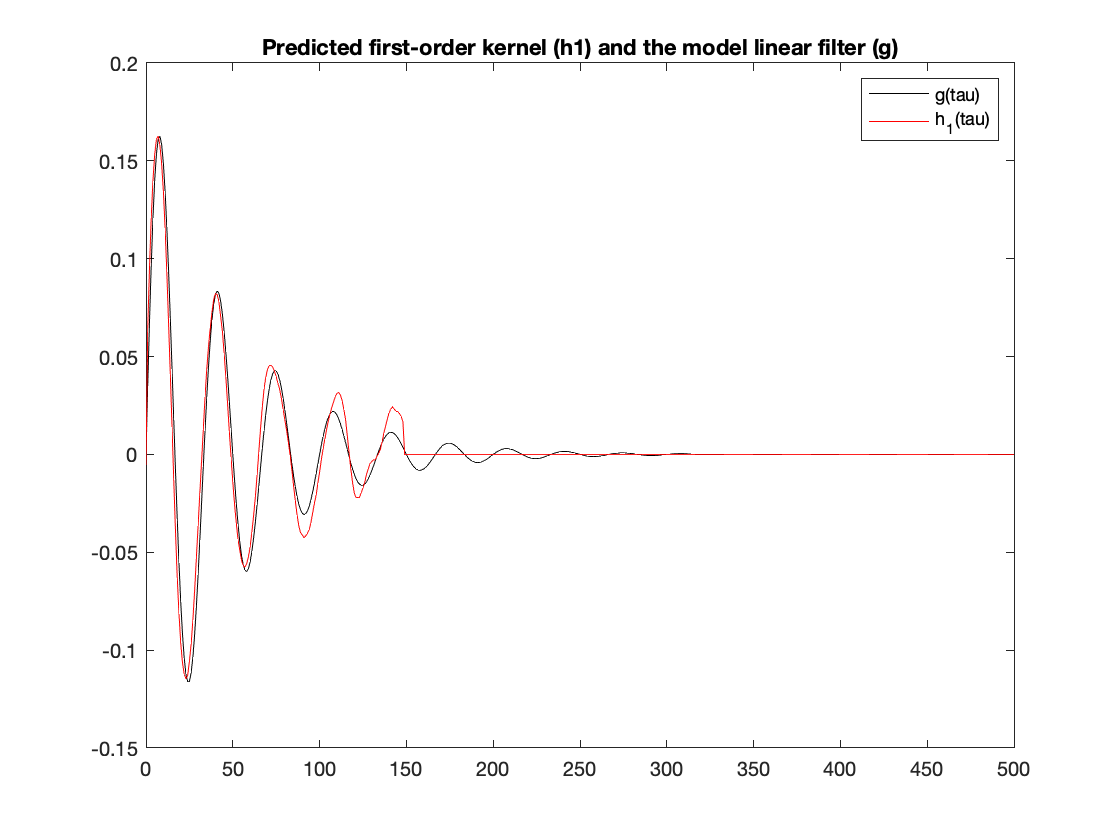

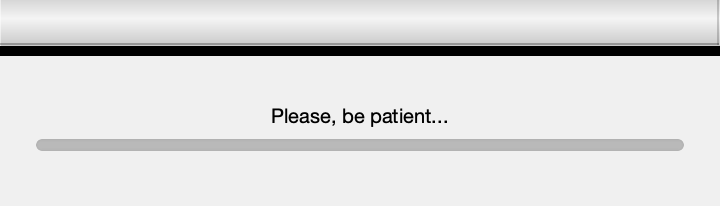

    1.0000



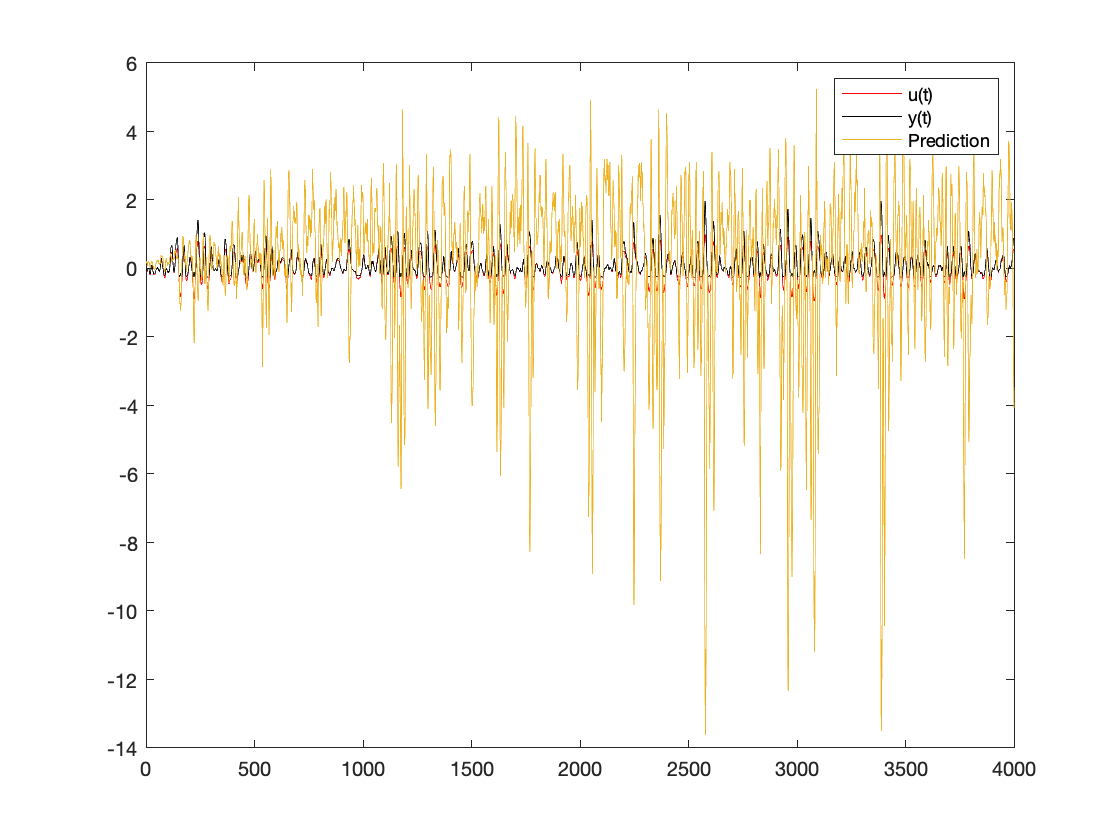

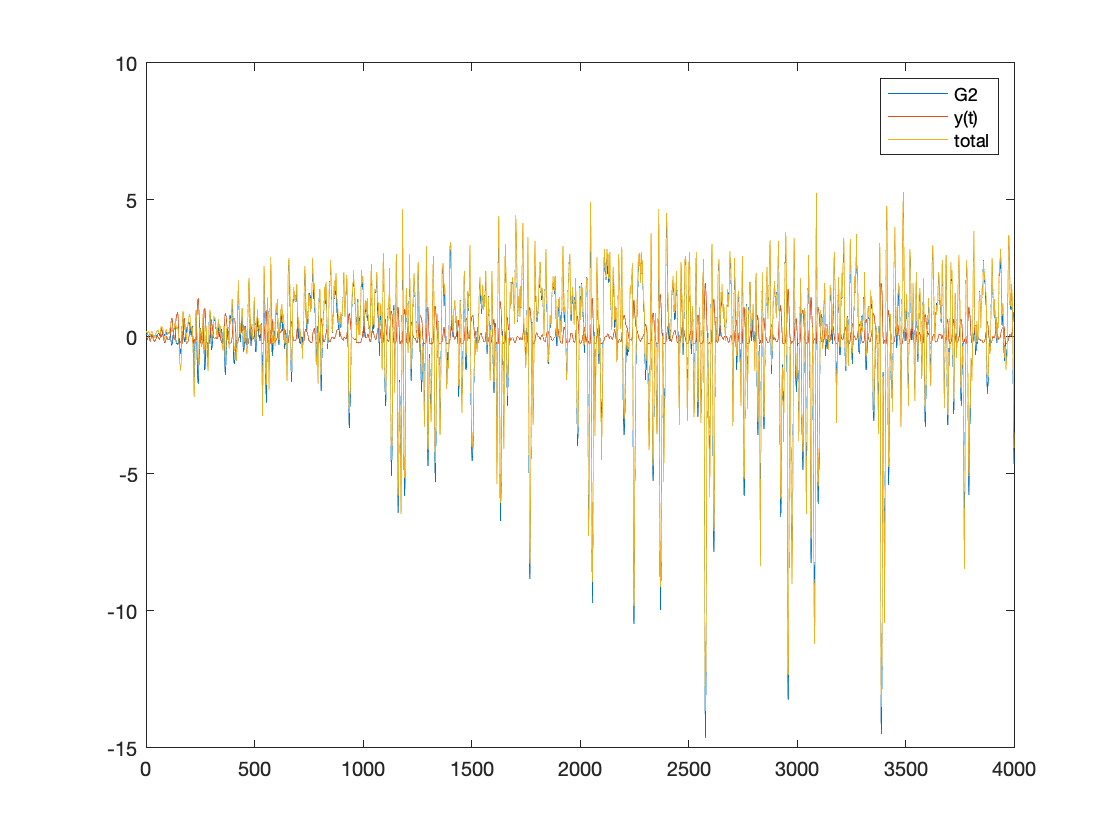

corr total and yt
    1.0000   -0.4082
   -0.4082    1.0000

corr G2 and yt
    1.0000   -0.5235
   -0.5235    1.0000

corr G1 and yt
    1.0000    0.8907
    0.8907    1.0000



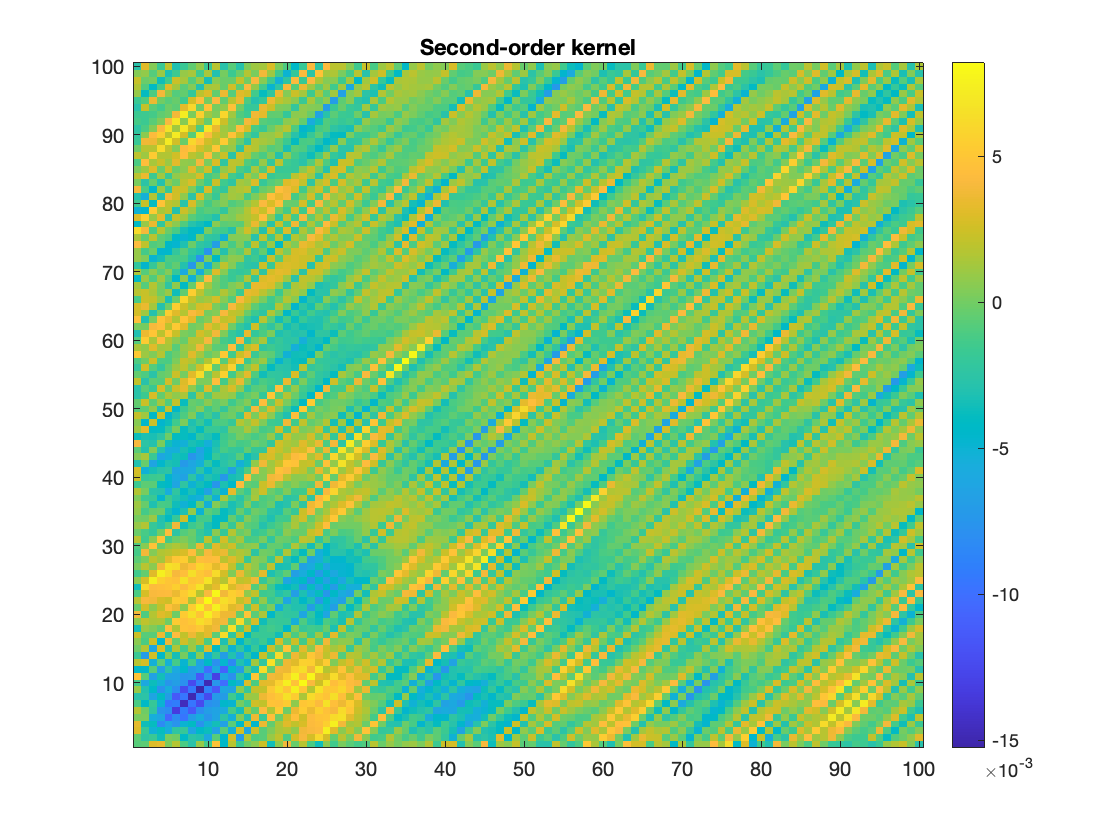

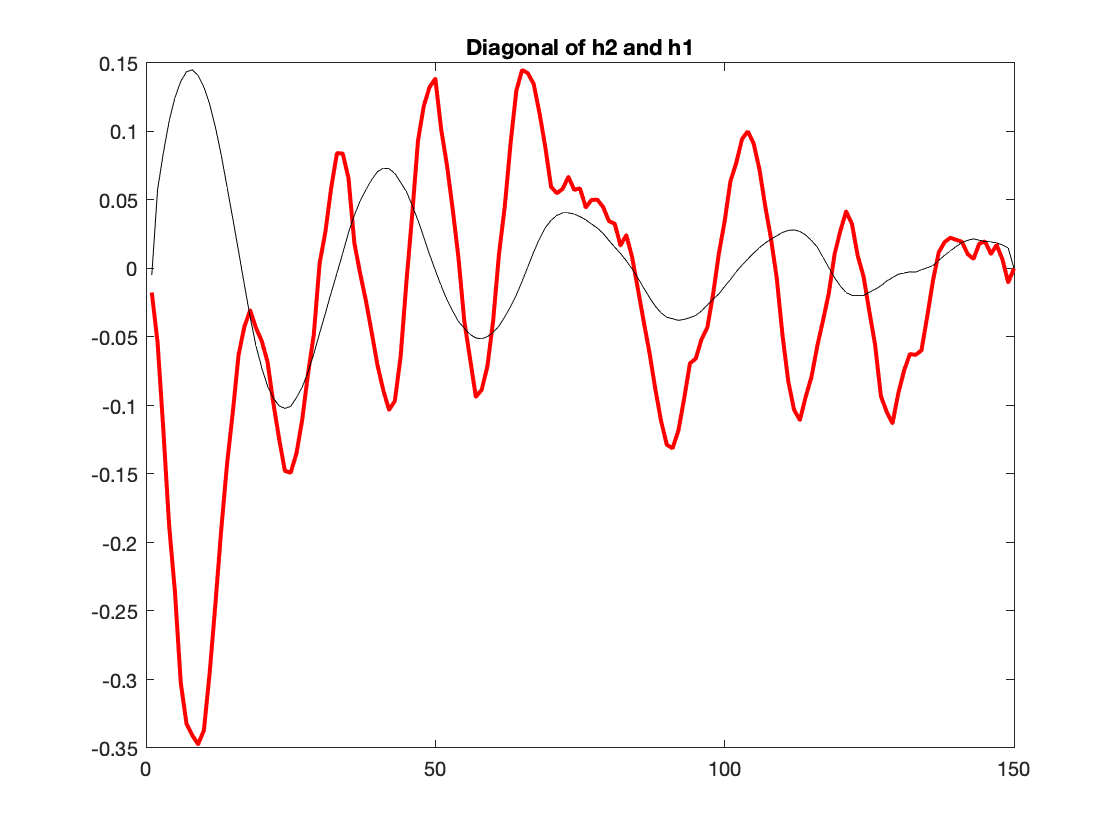

%[h0,h1,h2] = wiener(2,0); %(no nonlinearity)
%indeed see that h2 is not very informative for a system without
%nonlinearity
%[h0,h1,h2] = wiener(0,1); %(no linearity)
%indeed see that h1 does not perform well for a nonlinear system
[h0,h1,h2] = wiener(1,1); %we see that for higher b values the part that the G2 plays becomes larger, as is evident by the higher corrcoef values and something similar for a values and G1

%[h0,h1,h2] = wiener(5,1); %such a difference between the linear and non linear parts requires the sum of the kernals to be adjusted, eg. here G0+G1+0.2*G2 instead of G0+G1+G2

**Test of regstats:**

x=10*randn(100,1);
y=6*(x.^2)+40;
rst=regstats(y,x);
disp(rst);

        source: 'regstats'
             Q: [100×2 double]
             R: [2×2 double]
          beta: [2×1 double]
          covb: [2×2 double]
          yhat: [100×1 double]
             r: [100×1 double]
           mse: 9.5194e+05
       rsquare: 0.1394
    adjrsquare: 0.1306
      leverage: [100×1 double]
        hatmat: [100×100 double]
          s2_i: [100×1 double]
        beta_i: [2×100 double]
      standres: [100×1 double]
       studres: [100×1 double]
       dfbetas: [2×100 double]
         dffit: [100×1 double]
        dffits: [100×1 double]
      covratio: [100×1 double]
         cookd: [100×1 double]
         tstat: [1×1 struct]
         fstat: [1×1 struct]
        dwstat: [1×1 struct]



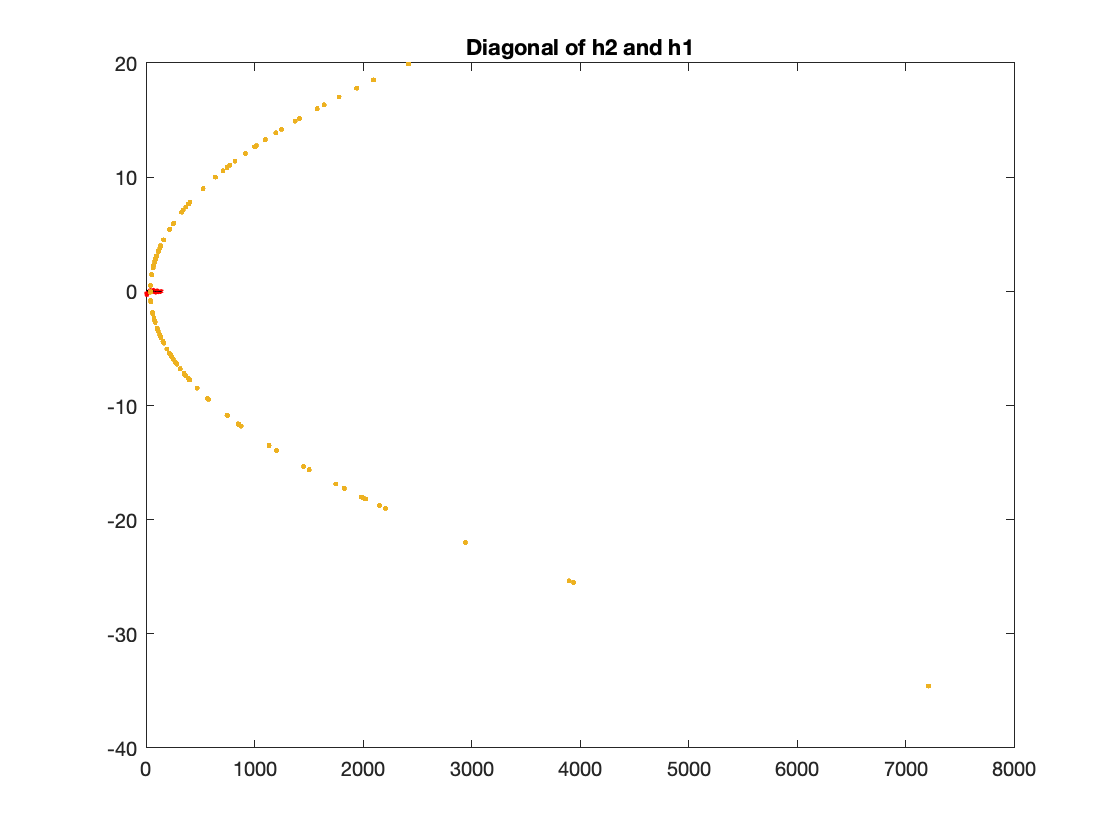

plot(y,x,'.');

**Now that we have played around with the wiener function for a while, and determined how the different parameters seem to work, we can try to work on the actual input files.**

close all;
P = std(gwnt)          % the power of the noise

P = 0.9986


h0=mean(yt);
disp(h0);

    0.0032



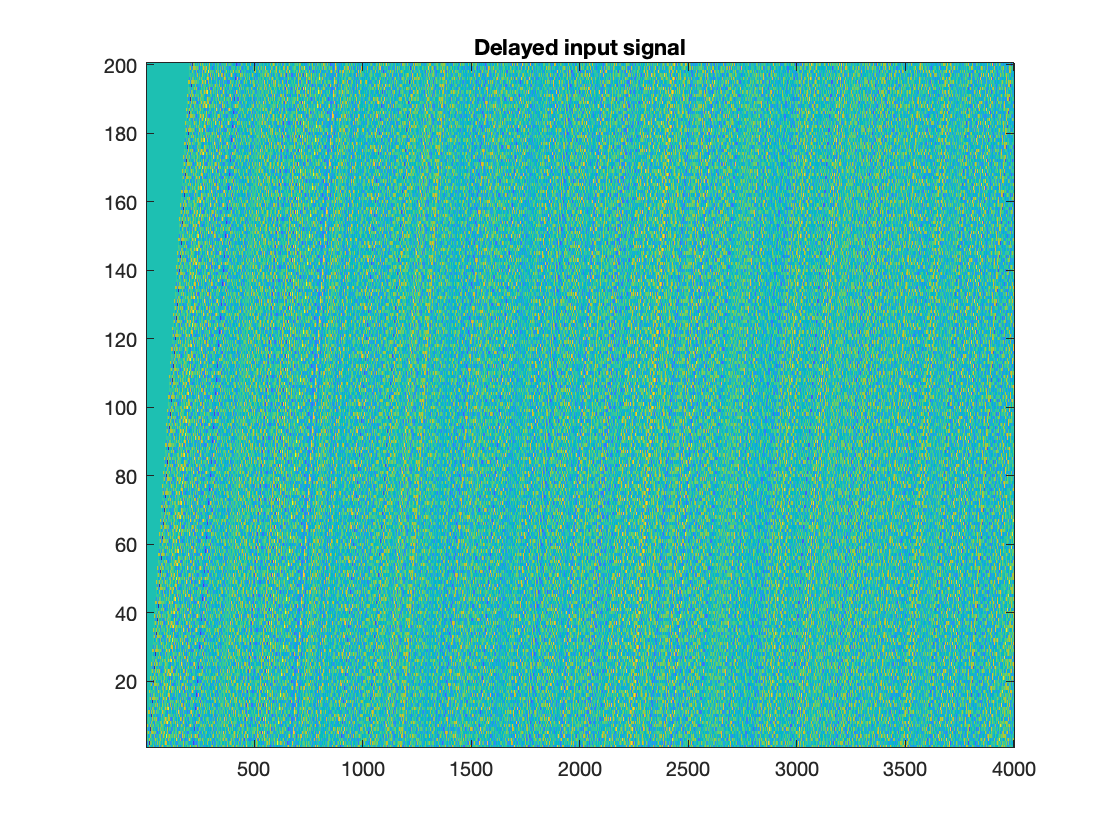

G0 = h0;       % the zero-order Wiener prediction
y0 = yt - G0;      % the Lee-Schetzen method: subtract h0 from the response

%  first order estimate: crosscorrelate
%
fi1 = phi_yx2(y0, gwnt, 200-1);   %first-order kernel

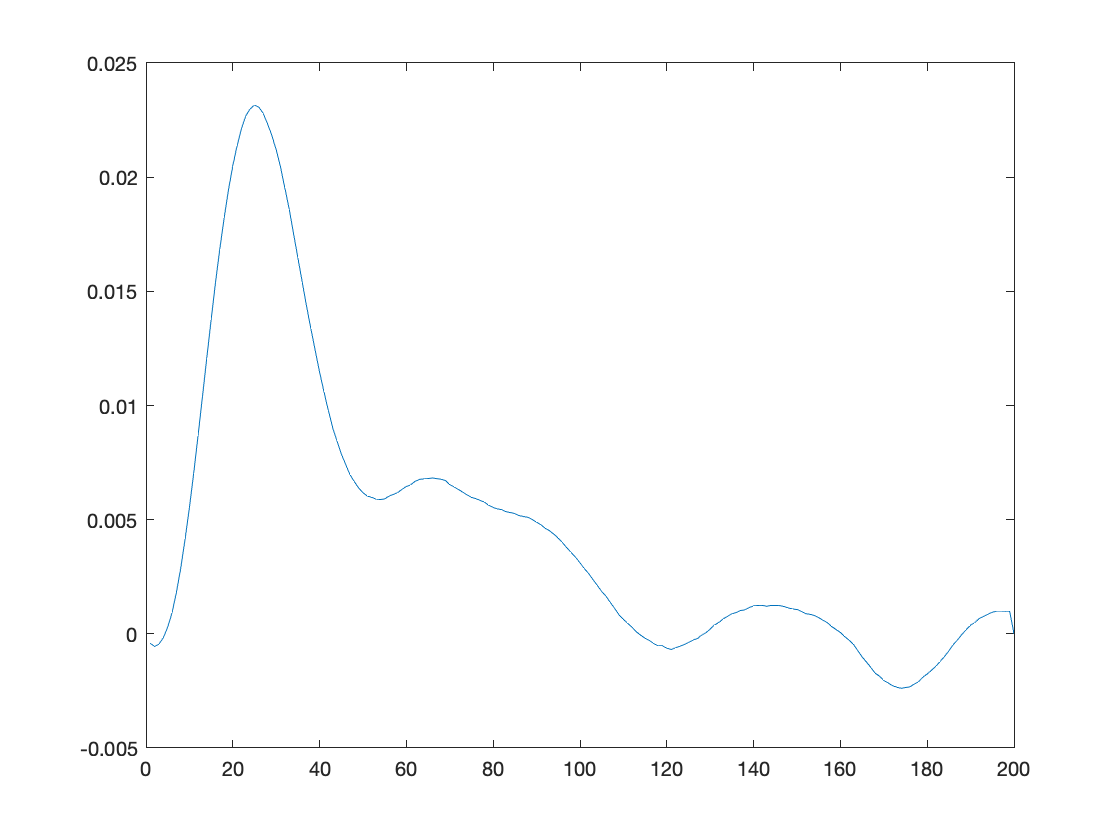

h1=fi1/P;       % only positive tau! 
h1(200:end)=0; %listened to the hint, this reduced the noise a lot indeed
%perhaps 80:end is better
figure(1)
plot(h1);

s=sum((h1)); %get a sum over h1 of one if we take away the absolute value, but get worse results
h1 = h1/s; % normalise the integral to one (this is a "tweaking point.." )
dt=1;
disp(sum(h1)*dt);

    1.0000



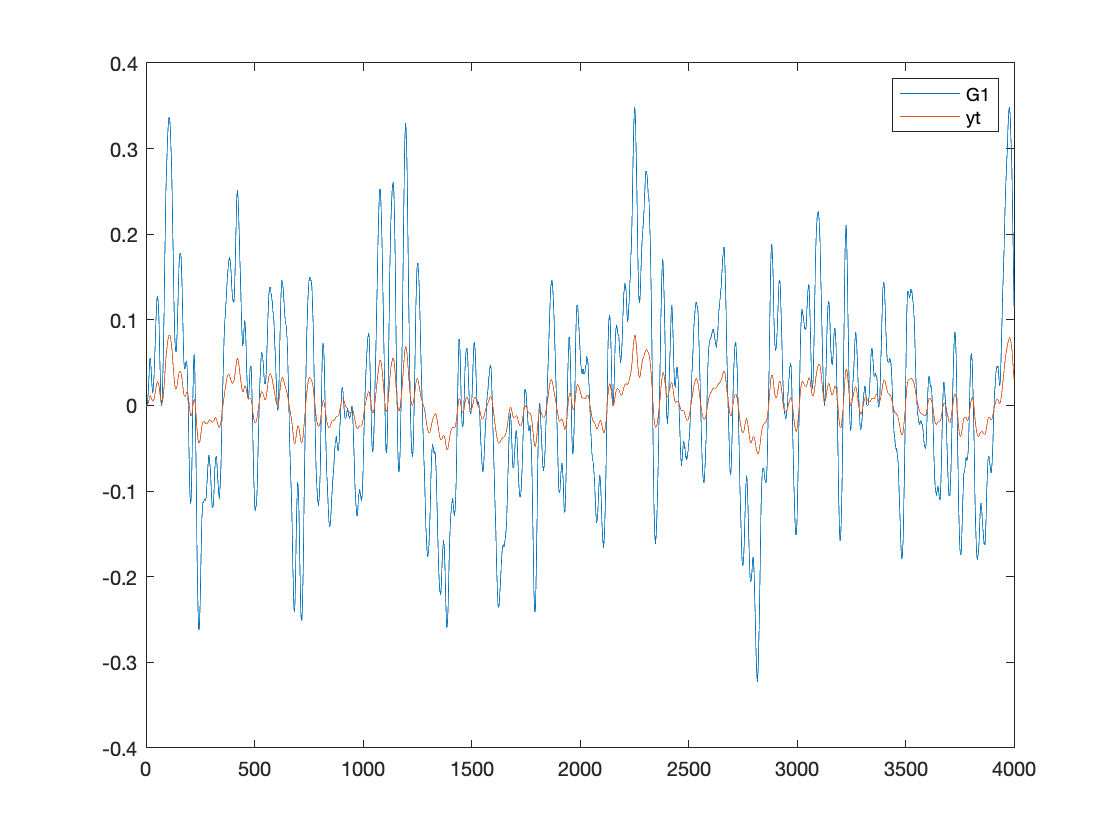


G1 = conv(gwnt, h1);      % 1e order Wiener prediction with the scaled kernel 
G1 = G1(1:length(gwnt));
figure(4)
plot(G1); %/5 for very close resemblance to yt 
hold on
plot(yt);
%plot(y1);
legend('G1','yt');
hold off

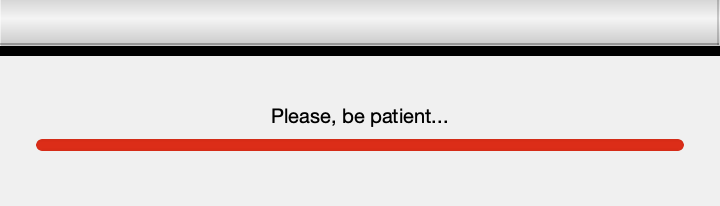

y1 = yt - G0 - G1;    % residue, corrected for G0 and G1

%
%    second order kernel: 3rd-order cross-correlation
%
fi2=phi_yxx2(y1, gwnt, 105); %can decrease the slope of the regression by decreasing the third parameter

h2=fi2/(2*P^2);         % the 2nd order Wiener kernel: only positive tau1, tau2 
%h2(1:200,1:200)=0;
s = sum(sum((h2)));  % total integral of the kernel
h2 = h2/s;              % normalize the kernel to one   
disp(sum(sum(h2))*dt);

    1.0000



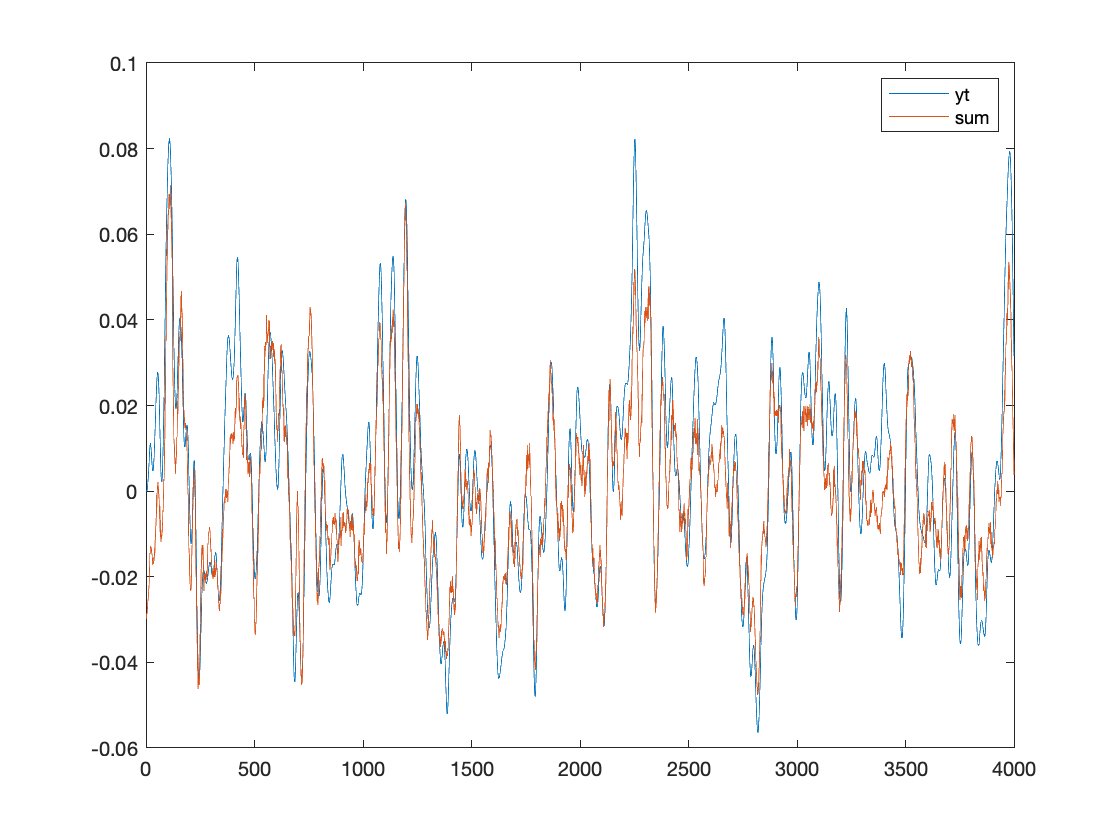


G2 = convh2xx(h2,gwnt,P);      % 1e order Wiener prediction with the scaled kernel 
G2=G2(1:length(gwnt));
figure(4)
plot(yt); 
hold on
%plot(G2);
plot((G0+G1+G2)/12.5);
legend('yt','sum');
%legend('G2','yt','sum');
hold off

disp("corr total and yt");

corr total and yt


disp(corrcoef((G0+G1+G2),yt));

    1.0000    0.9081
    0.9081    1.0000



disp("corr G2 and y1");

corr G2 and y1


disp(corrcoef((G2),y1));

    1.0000   -0.7279
   -0.7279    1.0000



disp("corr G1 and y0");

corr G1 and y0


disp(corrcoef((G1),y0));

    1.0000    0.9839
    0.9839    1.0000



disp("corr G1 and yt");

corr G1 and yt


disp(corrcoef((G0+G1),y0)); %very high in the case of G1/5

    1.0000    0.9839
    0.9839    1.0000



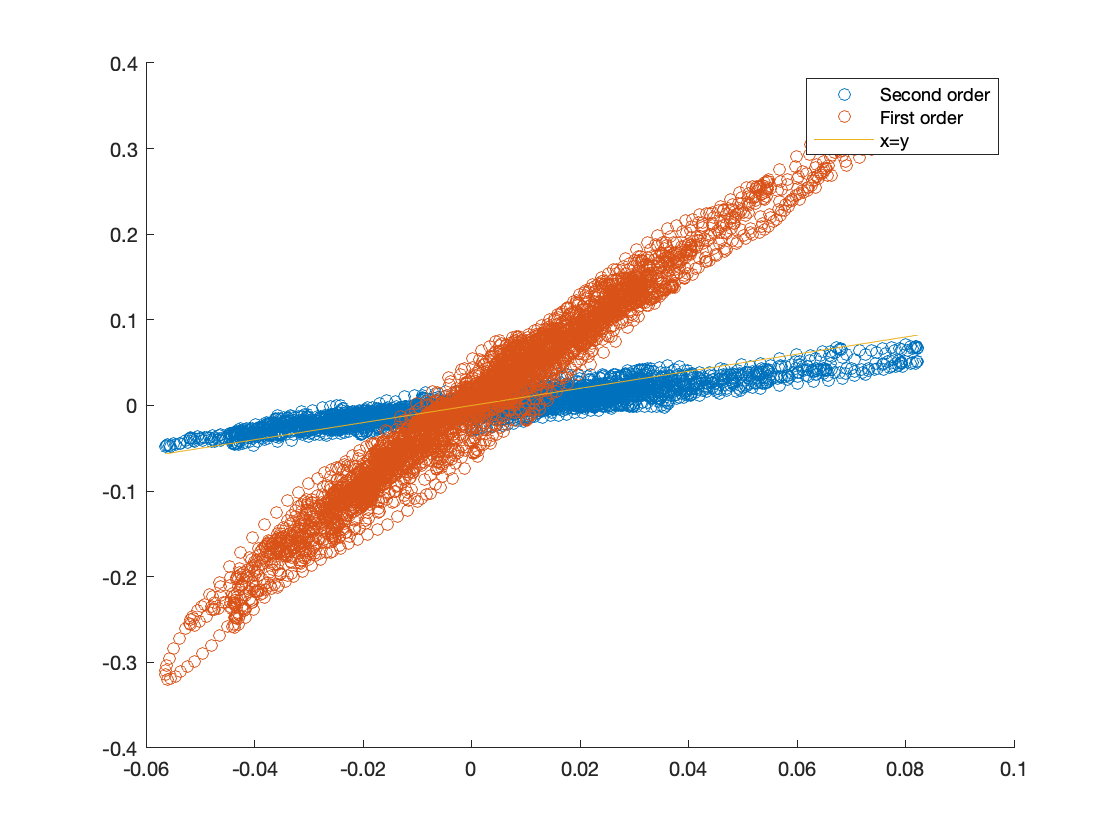

x_plt=linspace(min(yt),max(yt),10);
figure(5);
scatter(yt,(G0+G1+G2)/12.5);
hold on
scatter(yt,(G0+G1));
plot(x_plt,x_plt);
legend('Second order','First order','x=y');


h01=mean(output1);
G01 = h01; 
G11 = conv(input1, h1); 
G11=G11(1:length(input1));
G21 = convh2xx(h2,input1,P);
%G21=G21(1:length(gwnt));
disp("corr total and output1");

corr total and output1


disp(corrcoef((G01+G11+G21),output1));

    1.0000    0.9684
    0.9684    1.0000




h02=mean(output1);
G02 = h02; 
G12 = conv(input2, h1); 
G12=G12(1:length(input2));
G22 = convh2xx(h2,input2,P);
%G21=G21(1:length(gwnt));
disp("corr total and output2");

corr total and output2


disp(corrcoef((G02+G12+G22),output2));

    1.0000    0.9703
    0.9703    1.0000




h03=mean(output3);
G03 = h03; 
G13 = conv(input3, h1); 
G13=G13(1:length(input3));
G23 = convh2xx(h2,input3,P);
%G21=G21(1:length(gwnt));
disp("corr total and output3");

corr total and output3


disp(corrcoef((G03+G13+G23),output3));

    1.0000    0.9566
    0.9566    1.0000



%plot(yt);

Now working with the in and output files. The code below is from a previous trial of this exercise by me.

% clf('reset')
% input=input1;
% output=output1;
% P = std(output) % the power of the input
% 
% %the zeroth order as before
% h0=mean(input);
% G0 = h0;       % the zero-order Wiener prediction
% y0 = output - G0;      % the Lee-Schetzen method: subtract h0 from the response
% 
% %  first order estimate: crosscorrelate
% %
% zero_range=200;
% fi1 = phi_yx2(y0, input, length(input)-15);   %first-order kernel
% h1=fi1/P;       % only positive tau! 
% h1(zero_range:(8000-zero_range))=0; 
% 
% %the below was when comparing g1 with the input in the corrcoef
% %I do see a increase in the corrcoef values when not taking into acount the
% %data from around timestep 188 (the optimal value found for input1 was around 190)
% %then for input 2 this also resulted in relatively gigh postive values, but
% %then the input 3 turned out to be negative, but after a small search it
% %was found that the value for 188 was potitive for all three
% 
% s=sum((h1)); %get a sum over h1 of one if we take away the absolute value, but get worse results
% h1 = h1/s; % normalise the integral to one (this is a "tweaking point.." )
% dt=1;
% disp(sum(h1)*dt);
% 
% m1=max(h1);
% m2=max(input);
% m3=m1/m2;     
% 
% G1 = conv(input, h1);      % 1e order Wiener prediction with the scaled kernel 
% G1 = G1(1:length(input));
% figure(15)
% plot(G1);  
% hold on
% plot(gwnt);
% hold off
% legend('G1','output');
% disp(corrcoef(G1/m3,output));
% y1 = output - G0 - G1;
% 
% fi2=phi_yxx2(y1, input, 2000);              
% h2=fi2/(2*P^2);         % the 2nd order Wiener kernel: only positive tau1, tau2 
% s = sum(sum((h2)));  % total integral of the kernel
% h2 = h2/s;              % normalize the kernel to one   
% disp(sum(sum(h2))*dt);
% 
% G2 = convh2xx(h2,input,P);
% disp(corrcoef(G0+G1+G2,output));